# Test of trajectory corridors

This script is to test the implementation of the traj_box.m file.

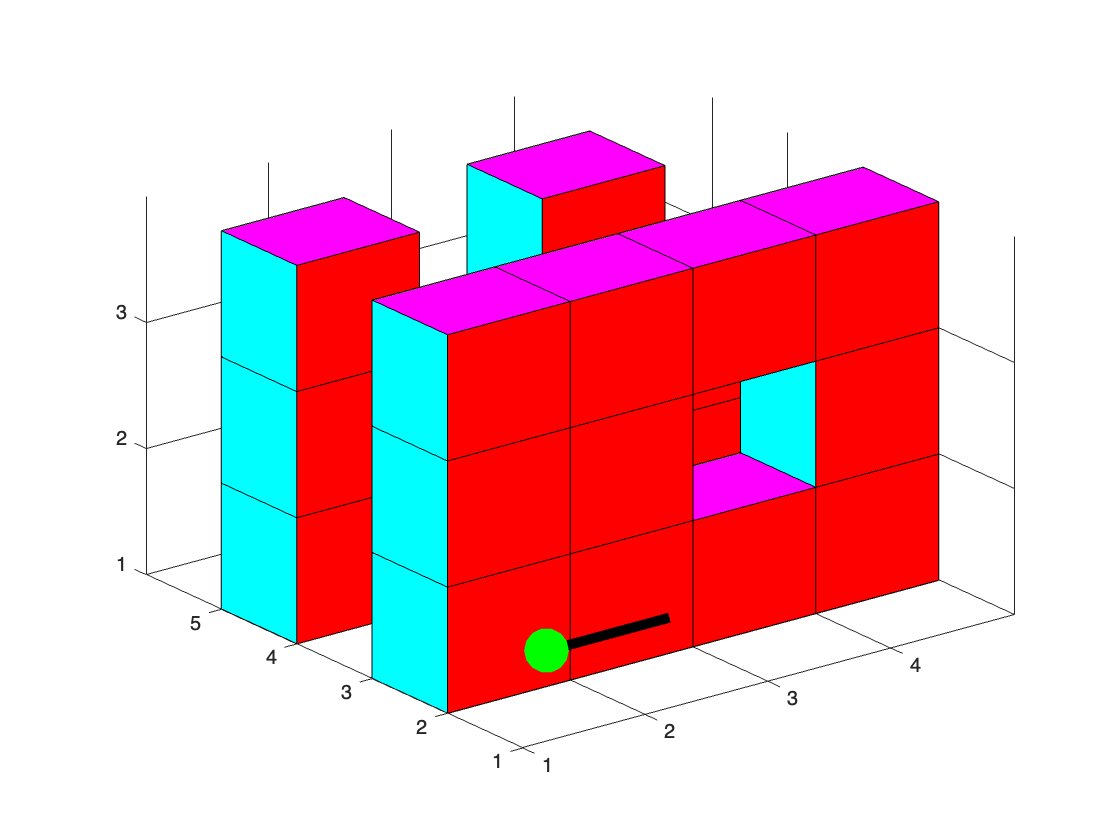

% First generate the route:
run("maze/exercise_4_files/map_script_3d.m"); % Either need route or route scaled

Add offset to route:

% Add offset
route

route =      1     1     1
     2     1     1
     3     1     1
     3     1     2
     3     2     2
     3     3     2
     3     3     3
     4     3     3
     4     4     3
     4     5     3



route(:,1) = route(:,1) + 0.5;
route(:,2) = route(:,2) + 0.5;
route(:,3) = route(:,3) + 0.5;

route

route =     1.5000    1.5000    1.5000
    2.5000    1.5000    1.5000
    3.5000    1.5000    1.5000
    3.5000    1.5000    2.5000
    3.5000    2.5000    2.5000
    3.5000    3.5000    2.5000
    3.5000    3.5000    3.5000
    4.5000    3.5000    3.5000
    4.5000    4.5000    3.5000
    4.5000    5.5000    3.5000



% These can act as waypoints ?!?

We wish to run these through the algorithm - both:

% first get cylinder:
% place 1
%start = [1.5 1.5 1.5];
%end1 = [3.5 1.5 2.5];

% place 2
%end2 = [3.5 2.5 2.5];

%omap = convert_to_occupancymap(map)
%cyl1 = get_cylinder(start, end1);
%cyl2 = get_cylinder(start, end2);
%obstruciton1 = check_obstruction(omap, cyl1)
%obstruciton2 = check_obstruction(omap, cyl2)

%clf
%hold on
%show(omap)
%show(cyl1)
%show(cyl2)

We test the entire thing

%start = [1.5 1.5 1.5]
%omap = convert_to_occupancymap(map)
%route
%no_waypoints = length(route);
%start_waypoint = route(1,:)
%prev_waypoint = route(1,:)

% Initialize corridors
%corridors.times = [];
%corridors.x_lower = [];
%corridors.x_upper = [];
%corridors.y_lower = [];
%corridors.y_upper = [];
%corridors.z_lower = [];
%corridors.z_upper = [];

%for wayp_idx = 2:no_waypoints
%    current_waypoint = route(wayp_idx, :);

    % Check for blockage between start waypoint and current waypoint:
%    cylinder = get_cylinder(start_waypoint, current_waypoint);
%    obstruction = check_obstruction(omap, cylinder);

%    if obstruction == 1
        % Idea - get the halfway point betweeen and check there
        % further decreasing the time
        
        % Calculate time:
        %corridors.times = [corridors.times ];
        %corridors.x_lower = [corridors.x_lower prev_waypoint(1)-0.5];
        %corridors.x_upper = [corridors.x_upper prev_waypoint(1)+0.5];
        %corridors.y_lower = [corridors.y_lower prev_waypoint(2)-0.5];
        %corridors.y_upper = [corridors.y_upper prev_waypoint(2)+0.5];
        %corridors.z_lower = [corridors.z_lower prev_waypoint(3)-0.5];
        %corridors.z_upper = [corridors.z_upper prev_waypoint(3)+0.5];

        %start_waypoint = prev_waypoint;
    %end
    %prev_waypoint = current_waypoint;
%end

corridors = get_traj_corridors(map, route)

corridors = struct with fields:
      times: [4 6 8 10]
    x_lower: [3 3 4 4]
    x_upper: [4 4 5 5]
    y_lower: [1 3 3 5]
    y_upper: [2 4 4 6]
    z_lower: [2 2 3 3]
    z_upper: [3 3 4 4]


 Functions

function obstruction = check_obstruction(omap, cylinder)
    npOpts = occupancyMap3DCollisionOptions(CheckNarrowPhase=true,ReturnDistance=true,ReturnVoxels=true);
    [npIsColliding,bpResults] = checkMapCollision(omap,cylinder,npOpts);
    obstruction = npIsColliding;    
end

function omap = convert_to_occupancymap(map)
    omap = occupancyMap3D();
    s = size(map);
    for level=1:s(3) % loop over each level
        for row=1:s(1) % loop over x
            for col=1:s(2)
                element = map(row, col, level);
                if element == 1
                    % Calculate coords:
                    x_coord = row + 0.5;
                    y_coord = col + 0.5;
                    z_coord = level + 0.5;
                    updateOccupancy(omap,[x_coord y_coord z_coord], 1);
                end
            end
        end
    end
    %show(omap)
end

function cyl = get_cylinder(start, end_)
    % First get direction unit vector
    dir_vec = end_ - start;

    % Then get midpoint between points
    midpoint = [(end_(1)+start(1))/2 (end_(2)+start(2))/2 (end_(3)+start(3))/2];

    % Then get cylinder:
    cyl = collisionCylinder(0.1,norm(dir_vec));
    
    % Normalize the vector
    dir_vec = dir_vec/norm(dir_vec);

    % Align
    rx = dir_vec(1);
    ry = dir_vec(2);
    rz = dir_vec(3);
    sin_alpha = ry/(sqrt(rx^2+ry^2));
    cos_alpha = rx/(sqrt(rx^2+ry^2));
    sin_beta = sqrt(rx^2+ry^2);
    cos_beta = rz;
    alpha = atan2(sin_alpha, cos_alpha);
    alpha(isnan(alpha))=0; % Edge case
    beta = atan2(sin_beta, cos_beta);
    beta(isnan(beta))=0; % Edge case
    % beta around y and then alpha around z
    maty = axang2tform([0 1 0 beta]);
    matz = axang2tform([0 0 1 alpha]);
    mat_t = trvec2tform(midpoint);
    % Reverse order, first rotate around y, then z then translate
    mat = mat_t*matz*maty;
    cyl.Pose = mat;
end

function corridors = get_traj_corridors(map, route)
    omap = convert_to_occupancymap(map);
    no_waypoints = length(route);
    start_waypoint = route(1,:);
    prev_waypoint = route(1,:);
    
    % Initialize corridors
    corridors.times = [];
    corridors.x_lower = [];
    corridors.x_upper = [];
    corridors.y_lower = [];
    corridors.y_upper = [];
    corridors.z_lower = [];
    corridors.z_upper = [];

    time = 0;
    
    for wayp_idx = 2:no_waypoints
        time = time+1;
        current_waypoint = route(wayp_idx, :);
    
        % Check for blockage between start waypoint and current waypoint:
        cylinder = get_cylinder(start_waypoint, current_waypoint);
        obstruction = check_obstruction(omap, cylinder);
    
        if obstruction == 1
            % Idea - get the halfway point betweeen and check there
            % further decreasing the time
            
            % Calculate time:
            corridors.times = [corridors.times time];
            corridors.x_lower = [corridors.x_lower prev_waypoint(1)-0.5];
            corridors.x_upper = [corridors.x_upper prev_waypoint(1)+0.5];
            corridors.y_lower = [corridors.y_lower prev_waypoint(2)-0.5];
            corridors.y_upper = [corridors.y_upper prev_waypoint(2)+0.5];
            corridors.z_lower = [corridors.z_lower prev_waypoint(3)-0.5];
            corridors.z_upper = [corridors.z_upper prev_waypoint(3)+0.5];
    
            start_waypoint = prev_waypoint;
        end
        prev_waypoint = current_waypoint;
    end
end